### Circuito 1 Circuito complejo desde Netlist en Excel

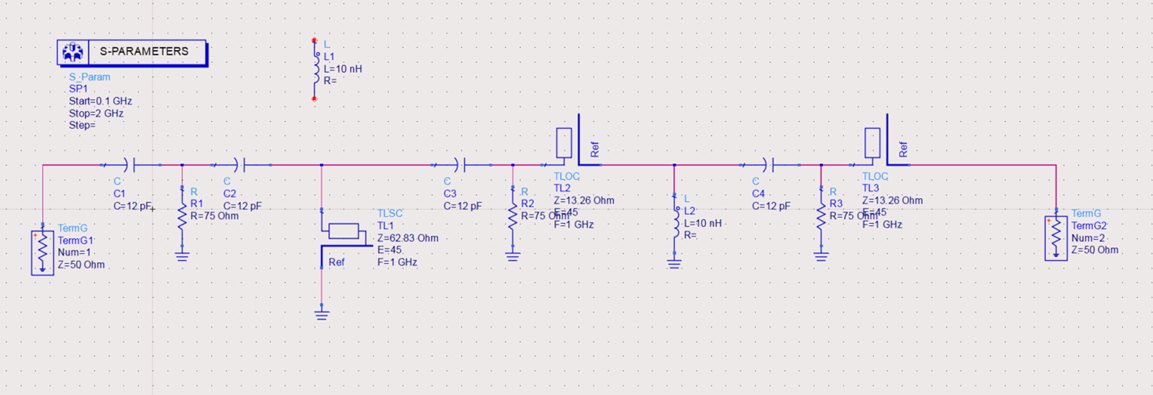

netlistTable = readtable('Netlist excel\4_Stubs_Netlist.xlsx')           

netlistTable = 11×7 table
     Nombre     NodoInicial    NodoFinal    componente     valor     longitudElectrica    Frecuencia
    ________    ___________    _________    __________    _______    _________________    __________

    {'C1'  }      {'N1'}        {'N3'}       {'C'  }      1.2e-11            0                  0   
    {'R1'  }      {'N3'}        {'N0'}       {'R'  }           75            0                  0   
    {'C2'  }      {'N3'}        {'N4'}       {'C'  }      1.2e-11            0                  0   
    {'SSC1'}      {'N4'}        {'N0'}       {'SSC'}        62.83           45              1e+09   
    {'C3'  }      {'N4'}        {'N5'}       {'C'  }      1.2e-11            0                  0   
    {'R2'  }      {'N5'}    

Stubs_Pruebas=sparameters('Touchstone files\ElementosDistribuidos\4_Stubs_PruebasProyectoSParams.s2p')

Stubs_Pruebas =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij




netlistCell= table2cell(netlistTable);
Frec_inicial=0.1E9;
Frec_final=2E9;
Muestreo=1000;
Z0=50;


SMatlab=SParametersFromNetlist(netlistCell,Frec_inicial,Frec_final,Muestreo,Z0);

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubCorto'
                    Z0: 62.8300
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Short'
              StubMode: 'Shunt'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [4 0 0 0]
            ParentPath: 'unnamed'


Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [5 6 0 0]
            ParentPath: 'unnamed'


Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen_1'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [7 2 0 0]
            ParentPath: 'unnamed'


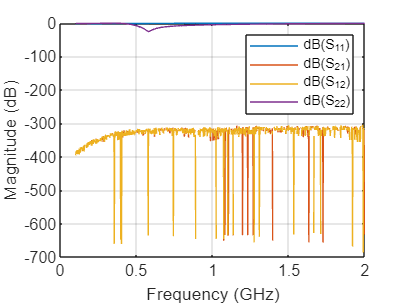

rfplot(SMatlab)

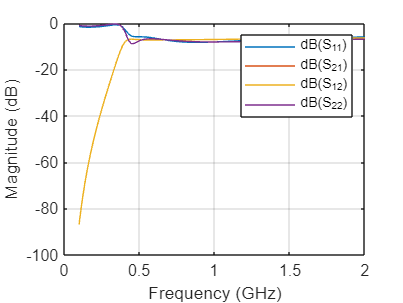

rfplot(Stubs_Pruebas)

### Circuito 2 Filtro con stubs desde LTspice

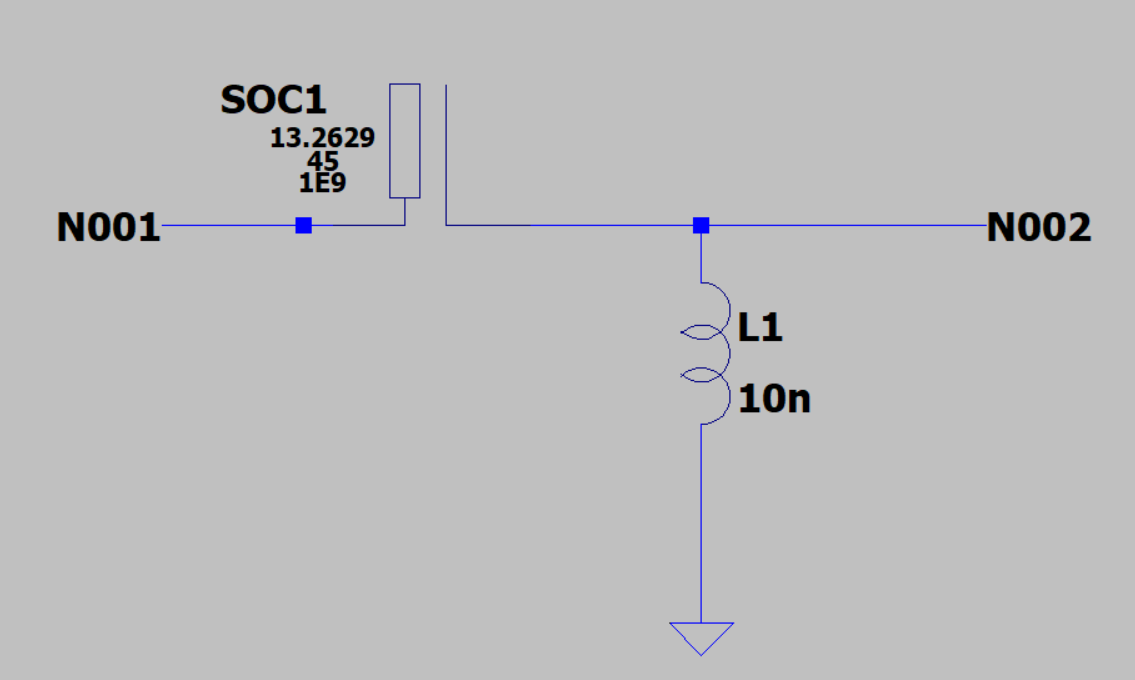

%Circuito 2 Pasa altas simple

%Importar netlist de Spice y convertir a celda
netlistSpicefile=('NetlistSpice\PasaAltasStubCapacitor.net')

netlistSpicefile = 'NetlistSpice\PasaAltasStubCapacitor.net'

netlistSpiceCell=Netlist2CellArray(netlistSpicefile)

netlistSpiceCell = 2×7 cell array
    {'SOC1'}    {'N001'}    {'N002'}    {'SOC'}    {[   13.2629]}    {[45]}    {[1.0000e+09]}
    {'L1'  }    {'N002'}    {'0'   }    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}



% Importar paraemtros S de touchstone
S_Touchstone=sparameters('Touchstone files\ElementosDistribuidos\StubPasaAltasSParams2.s2p')

S_Touchstone =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij



%Calcular parametros S con funcion
SMatlab2=SParametersFromNetlist(netlistSpiceCell,Frec_inicial,Frec_final,Muestreo,Z0)

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13.2629
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


SMatlab2 =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [1000×1 double]
     Parameters: [2×2×1000 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


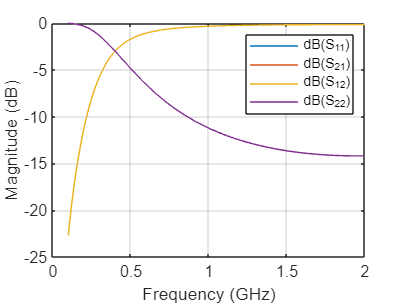


%Graficar para comparar
rfplot(S_Touchstone)

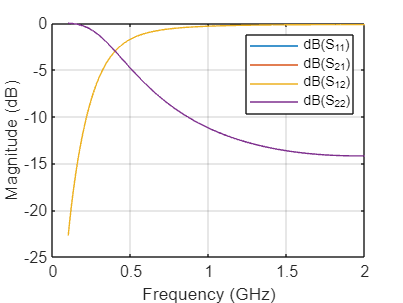

rfplot(SMatlab2)

### Circuito 3 Complejo desde Ltspice

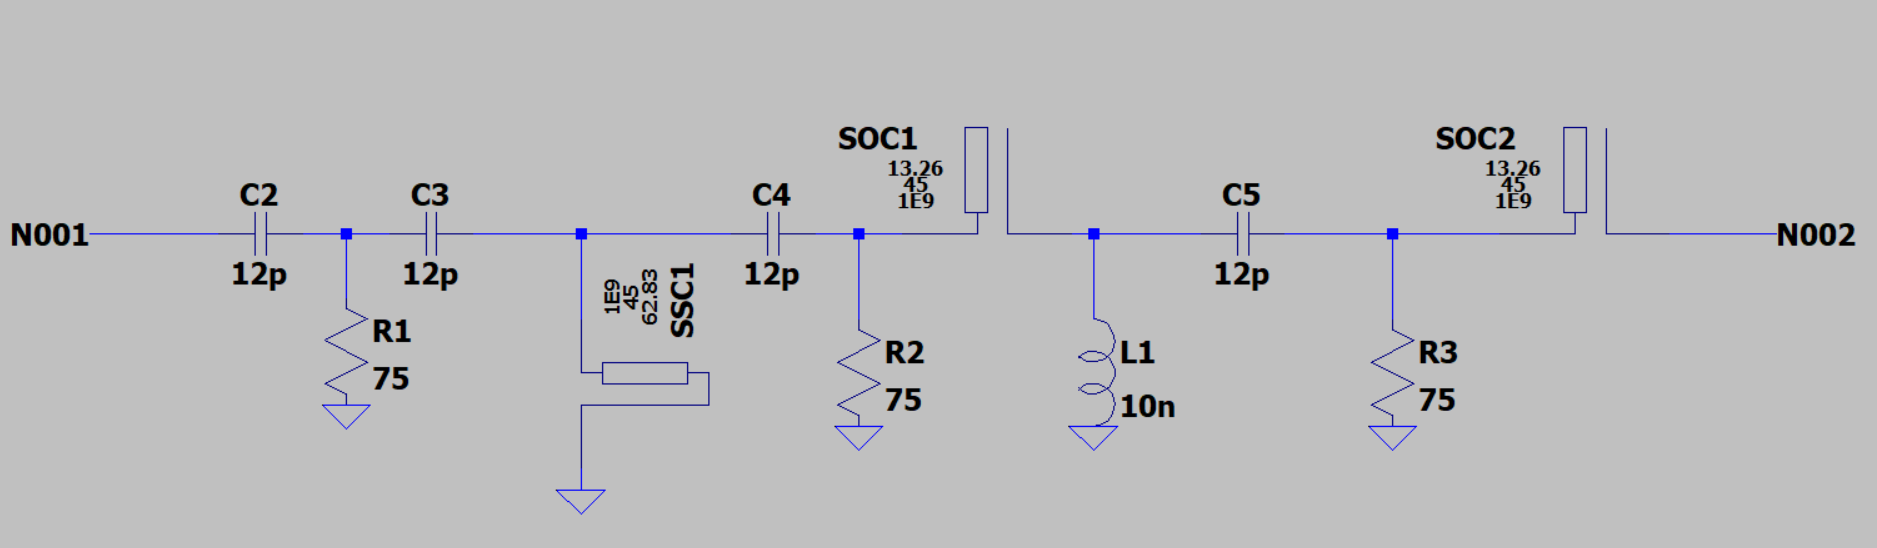

%Importar netlist de Spice y convertir a celda
netlistSpicefile=('NetlistSpice\CircuitoComplejoStubs.net')

netlistSpicefile = 'NetlistSpice\CircuitoComplejoStubs.net'

netlistSpiceCell=Netlist2CellArray(netlistSpicefile)

Error using feof
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in SParametersFromNetlist_Pruebas>Netlist2CellArray (line 48)
    while(~feof(fileID))


%Calcular parametros S con funcion
SMatlab3=SParametersFromNetlist(netlistSpiceCell,Frec_inicial,Frec_final,Muestreo,Z0)

%Graficar para comparar
rfplot(Stubs_Pruebas)
rfplot(SMatlab3)

### Circuito 4 Linea de Transmision

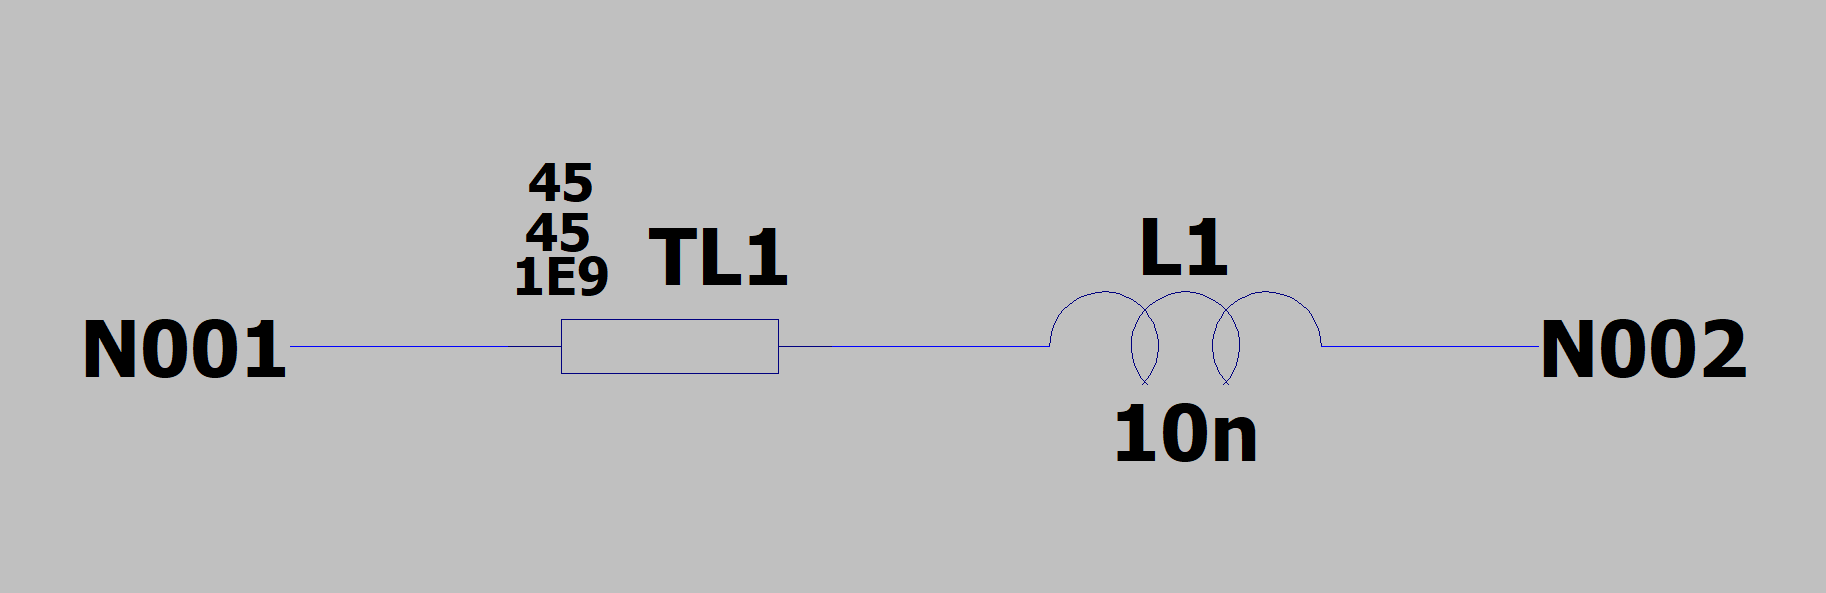

clear all
Frec_inicial=0.1E9;
Frec_final=2E9;
Muestreo=1000;
Z0=50;

netlist_TLfile='NetlistSpice\LineaTransmision.net'

netlist_TLfile = 'NetlistSpice\LineaTransmision.net'

netlist_TL=Netlist2CellArray(netlist_TLfile)

netlist_TL = 2×7 cell array
    {'L1' }    {'N003'}    {'N002'}    {'L' }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'TL1'}    {'N001'}    {'N003'}    {'TL'}    {[        45]}    {[45]}    {[1.0000e+09]}



SMatlab4=SParametersFromNetlist(netlist_TL,Frec_inicial,Frec_final,Muestreo,Z0)

TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [1 3 0 0]
            ParentPath: 'unnamed'


SMatlab4 =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [1000×1 double]
     Parameters: [2×2×1000 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


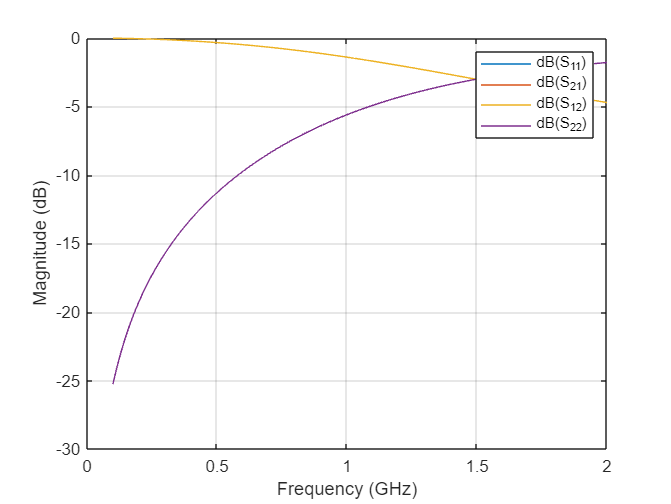

rfplot(SMatlab4)

function Netlist_CellArray = Netlist2CellArray(netlist_file)
    fileID= fopen(netlist_file,'r','n','UTF-8');
    
    n=1;
    pat= lettersPattern;
    
    while(~feof(fileID))
        nline = fgetl(fileID);
        if(~contains(nline,'.end') && ~contains(nline,'*') && ~contains(nline,'.backanno')) 
           splitted_nline = strsplit(nline);
           NumVal= sip2num(splitted_nline{:,4});
           
           %Define the type of element
           elem_Type = splitted_nline{:,1};
           elem_Type = cell2mat(extract(elem_Type,pat));
           %elem_Type(1,1);
    
           %For stubs and tranmision lines get Bl and frequency
           if elem_Type=="SOC" || elem_Type=="SSC" || elem_Type=="TL" 
               Bl= str2num(splitted_nline{:,5});
               freq=str2num(splitted_nline{:,6});
           else
               Bl=0;
               freq=0;
           end
    
           %Create custom cell array from netlist info 
           %Name, 1st Node, 2nd Node, type, Value
           Netlist_CellArray(n,:) = [splitted_nline{:,1}, splitted_nline{:,2}, splitted_nline{:,3}, {elem_Type}, {NumVal}, Bl, freq]; 
           n=n+1;
        end
    end
end   

